Cryogenic Aerogels Analysis 

This code is to do a preliminary analysis based on aerogels. A comparison of various aerogel materials is done as a metric for Thermal Protection Systems (TPS) for space launch vehicles. 

Based on the paper - https://www.sciencedirect.com/science/article/pii/S0011227505001578

Thermal Conductivity - 

    Lower thermal conductivity indicates better insulation. 

    k can be better assessed over a range of temperatures to see how the

    material behaves in the varying conditions of space 

%% q = -k*A*dt/dx 

    k is thermal conductivity

    q is the heat flux 

    A is the cross sectional area of the insulating material

    dT is the temperature difference

    dX is thickness of material

SPECIFIC HEAT CAPACITY (Cp) 

    Indicates material's ability to store heat. Materials with higher Cp

    can absorb more heat without a significant rise in temperature

    which can be crititcal during re-entry phases

%% Q = m*Cp*delta_T

    Q is the heat energy absorbed or released 

    m is the mass

    Delta T is the change in temperature

DENSITY - Lower density materials offer less weight to the launch vehicle

which is important for launch applications 

THERMAL EXPANSION COEFFICIENT - This mtric is improtant for understanding

how the materials dimensions change with temperature, which affects its

structural integrity ad mechanical stabilut 

t = linspace (-273, 1000, 100) 

t = 1.0e+03 *

   -0.2730   -0.2601   -0.2473   -0.2344   -0.2216   -0.2087   -0.1958   -0.1830   -0.1701   -0.1573   -0.1444   -0.1316   -0.1187   -0.1058   -0.0930   -0.0801   -0.0673   -0.0544   -0.0415   -0.0287   -0.0158   -0.0030    0.0099    0.0227    0.0356    0.0485    0.0613    0.0742    0.0870    0.0999    0.1128    0.1256    0.1385    0.1513    0.1642    0.1771    0.1899    0.2028    0.2156    0.2285    0.2413    0.2542    0.2671    0.2799    0.2928    0.3056    0.3185    0.3314    0.3442    0.3571


k = 0.023 % Thermal conductivity of aerogel 0.0792 W/m·K

k = 0.0230

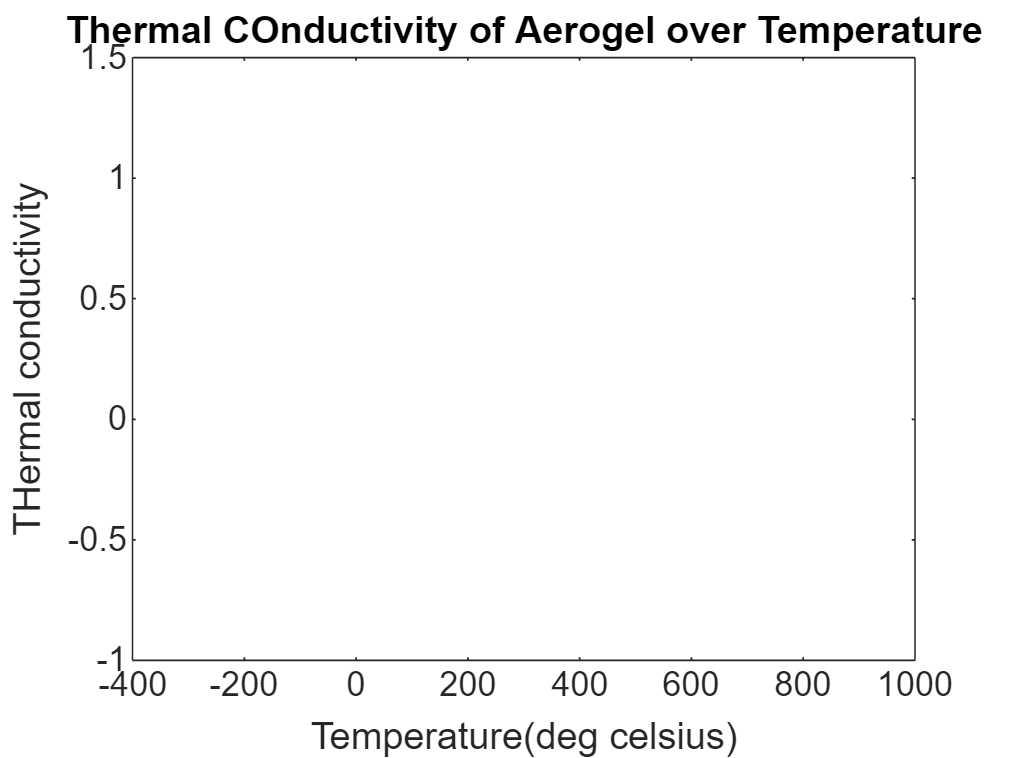

plot (t,k)
xlabel('Temperature(deg celsius)')
ylabel('THermal conductivity')
title('Thermal COnductivity of Aerogel over Temperature')

% Define cold vacuum pressure range (in millitorr)
pressureRange = logspace(-2, 6, 100); % from 0.01 to 1,000,000 millitorr

% Define thermal conductivity values for aerogel and other materials
% Note: These values should be based on your specific experimental data or literature
% For illustration, we use hypothetical data
thermalConductivityAerogel = 1e-3 * pressureRange.^0.5; % Hypothetical relationship
thermalConductivitySprayFoam = 0.01 + 0 * pressureRange; % Constant as an example
thermalConductivityPerlitePowder = 0.02 + 1e-6 * pressureRange; % Hypothetical relationship
thermalConductivityMLI = 0.005 + 5e-7 * pressureRange; % Hypothetical relationship

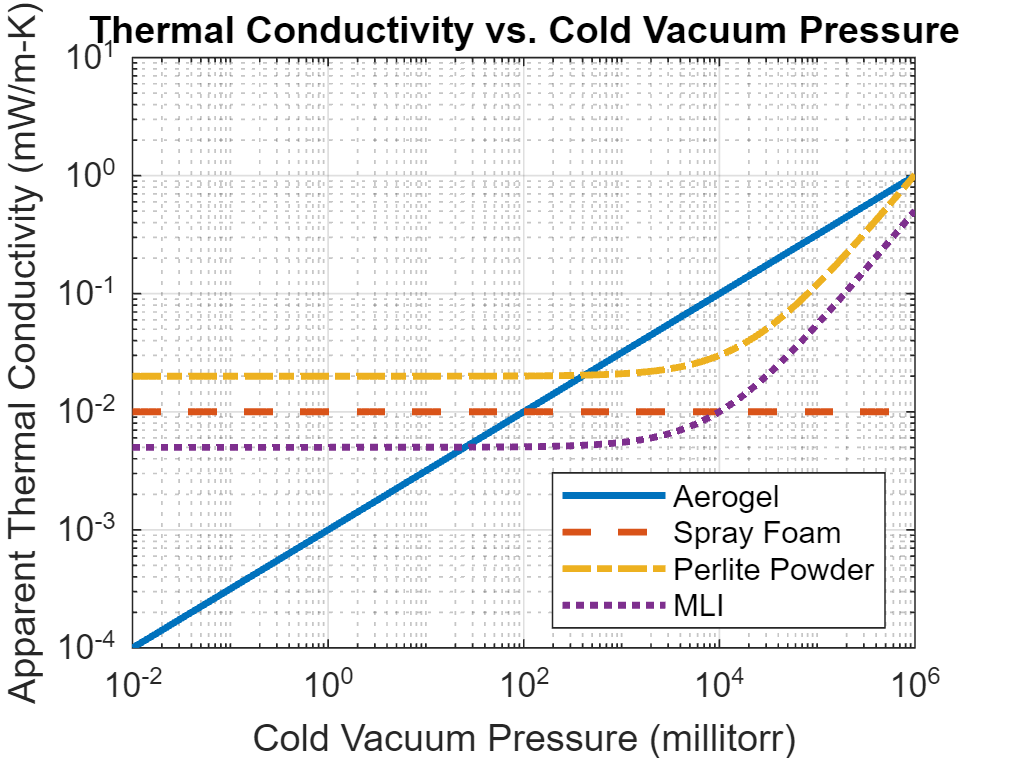

figure;
loglog(pressureRange, thermalConductivityAerogel, 'LineWidth', 2);
hold on;
loglog(pressureRange, thermalConductivitySprayFoam, '--', 'LineWidth', 2);
loglog(pressureRange, thermalConductivityPerlitePowder, '-.', 'LineWidth', 2);
loglog(pressureRange, thermalConductivityMLI, ':', 'LineWidth', 2);
hold off;

xlabel('Cold Vacuum Pressure (millitorr)');
ylabel('Apparent Thermal Conductivity (mW/m-K)');
title('Thermal Conductivity vs. Cold Vacuum Pressure');
legend('Aerogel', 'Spray Foam', 'Perlite Powder', 'MLI', 'Location', 'best');
grid on;